clear
close all
clc

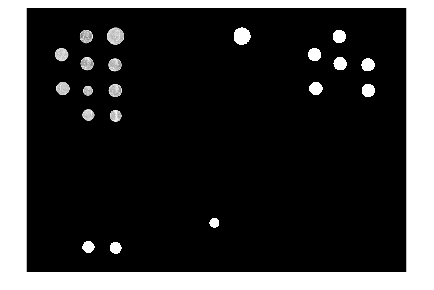

coinImage = imread("../../data/Data/MathWorks Images/coinImage.png");
coinImageGray = im2gray(coinImage);
[coinMask,maskedCoinImage] = segmentImage1(coinImageGray);
%imshow(maskedCoinImage)
coinSizes = regionprops("table",coinMask,["Area","Perimeter"]);
coin50Mask = bwpropfilt(coinMask,"Perimeter",[380,400]);
coinQuarterMask = bwpropfilt(coinMask,"Perimeter",[300,315]);
coinNickelMask = bwpropfilt(coinMask,"Perimeter",[270,280]);
coinDimeMask = bwpropfilt(coinMask,"Perimeter",[200,250]);
montage({maskedCoinImage,coin50Mask,coinQuarterMask,coinNickelMask,coinDimeMask})

nDimes = size(regionprops("table",coinDimeMask,"all"),1);
nNickels = size(regionprops("table",coinNickelMask,"all"),1);
nQuarters = size(regionprops("table",coinQuarterMask,"all"),1);
nFiftyCents = size(regionprops("table",coin50Mask,"all"),1);
USD = nDimes*0.10 + nNickels*0.05 + nQuarters*0.25 + nFiftyCents*0.50;

function [BW,maskedImage] = segmentImage1(X)
%segmentImage イメージの領域分割アプリから自動生成されたコードを使用してイメージをセグメント化
%  [BW,MASKEDIMAGE] = segmentImage(X) イメージの領域分割アプリから自動生成されたコードを使用してイメージ X
%  をセグメント化します。最終セグメンテーションは BW で返され、マスク イメージは MASKEDIMAGE で返されます。

% Auto-generated by imageSegmenter app on 16-Feb-2023
%----------------------------------------------------


% 空のマスクを作成
BW = false(size(X,1),size(X,2));

% イメージのしきい値処理 - グローバルしきい値
BW = imbinarize(im2gray(X));

% 穴の塗りつぶし
BW = imfill(BW, 'holes');

% default によるマスクのオープン
radius = 2;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end